# Example using generic control input with cycles

We use a generic control input, as described in [json schema documentation](https://github.com/BattMoTeam/BattMo/blob/main/Utilities/JsonSchemas/GenericControl.schema.json).

## Input setup

We load material parameter input parameters

jsonstruct_material = parseBattmoJson(fullfile('ParameterData'        , ...
                                               'BatteryCellParameters', ...
                                               'LithiumIonBatteryCell', ...
                                               'lithium_ion_battery_lco_graphite.json'));

We load geometry parameter input parameters

jsonstruct_geometry = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'geometryChen.json'));

We load the generic control parameter we want to use

jsonstruct_control  = parseBattmoJson(fullfile('Examples', 'JsonDataFiles', 'generic_step_control_cycle_example.json'));

We print it to command window

viewStruct(jsonstruct_control)

{
  "Control": {
    "controlPolicy": "Generic",
    "controlsteps": [
      {
        "controltype": "cycle",
        "numberOfcycles": 3,
        "cycleControlSteps": [
          {
            "controltype": "current",
            "value": 5,
            "direction": "discharge",
            "termination": {
              "quantity": "voltage",
              "value": 3,
              "comparison": "below"
            },
            "timeStepSize": 100
          },
          {
            "controltype": "voltage",
            "value": 3,
            "termination": {
              "quantity": "current",
              "value": 0.0001,
              "comparison": "absolute value below"
            },
            "timeStepSize": 100
          },
          {
            "controltype": "current",
            "value": 5,
            "direction": "charge",
            "termination": {
              "quantity": "voltage",
              "value": 4,
              "comparison": "above"
          

We remove the fields that are not relevant for this example. This is done to simplify the input parameters and focus on the relevant aspects of the model.

jsonstruct_material = removeStructFields(jsonstruct_material              , ...
                                             {'Control', 'DRate'}             , ...
                                             {'Control', 'controlPolicy'}     , ...
                                             {'Control', 'upperCutoffVoltage'}, ...
                                             {'Control', 'rampupTime'}        , ...
                                             {'Control', 'lowerCutoffVoltage'});

We merge all the input structures

jsonstruct = mergeStructs({jsonstruct_material, ...
                               jsonstruct_geometry, ...
                               jsonstruct_control});

We do not include thermal effects and the current collectors in this example to simplify the model.

jsonstruct.use_thermal                = false;
jsonstruct.include_current_collectors = false;

We run the simulation

output = runBattery(jsonstruct);

Solving timestep 1: Solving timestep 2: 00 Seconds                                        -> 200 Seconds
Solving timestep 3: 00 Seconds                                         -> 300 Seconds
Solving timestep 4: 00 Seconds                                          -> 400 Seconds
Solving timestep 5: 00 Seconds                                           -> 500 Seconds
Solving timestep 6: 00 Seconds                                            -> 600 Seconds
Solving timestep 7: 00 Seconds                                             -> 700 Seconds
Solving timestep 8: 00 Seconds                                              -> 800 Seconds
Solving timestep 9: 00 Seconds                                               -> 900 Seconds
Solving timestep 10: 00 Seconds                                                -> 1000 Seconds
Solving timestep 11: 000 Seconds                                       -> 1100 Seconds
Solving timestep 12: 100 Seconds                                       -> 1200 Seconds
Sol

Solver failure after 4 iterations for timestep of length 100 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 50 Seconds. Cutting timestep.
Solving timestep 49:  Hour, 1200 Seconds                               -> 1 Hour, 1300 Seconds
Solving timestep 50:  Hour, 1300 Seconds                               -> 1 Hour, 1400 Seconds
Solving timestep 51:  Hour, 1400 Seconds                               -> 1 Hour, 1500 Seconds
Solving timestep 52:  Hour, 1500 Seconds                               -> 1 Hour, 1600 Seconds
Solving timestep 53:  Hour, 1600 Seconds                               -> 1 Hour, 1700 Seconds
Solving timestep 54:  Hour, 1700 Seconds                               -> 1 Hour, 1800 Seconds
Solving timestep 55:  Hour, 1800 Seconds                               -> 1 Hour, 1900 Seconds
Solving timestep 56:  Hour, 1900 Seconds                               -> 1 Hou

Solver failure after 4 iterations for timestep of length 100 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 50 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 41 Seconds, 666 Milliseconds. Cutting timestep.
Solving timestep 99:  Hours, 2600 Seconds                               -> 2 Hours, 2700 Seconds
Solving timestep 100:  Hours, 2700 Seconds                               -> 2 Hours, 2800 Seconds
Solving timestep 101:  Hours, 2800 Seconds                               -> 2 Hours, 2900 Seconds
Solving timestep 102:  Hours, 2900 Seconds                               -> 2 Hours, 3000 Seconds
Solving timestep 103:  Hours, 3000 Seconds                               -> 2 Hours, 3100 Seconds
Solving timestep 104:  Hours, 3100 Seconds                               -> 2 Hours, 3200 Seconds
Solving timestep 105:  Hours, 3200 Seconds   

Solver did not converge in 10 iterations for timestep of length 100 Seconds. Cutting timestep.
Solver did not converge in 10 iterations for timestep of length 50 Seconds. Cutting timestep.
Solving timestep 150:  Hours, 500 Seconds                                  -> 4 Hours, 600 Seconds
Solving timestep 151:  Hours, 600 Seconds                                  -> 4 Hours, 700 Seconds
Solving timestep 152:  Hours, 700 Seconds                                  -> 4 Hours, 800 Seconds
Solving timestep 153:  Hours, 800 Seconds                                  -> 4 Hours, 900 Seconds
Solving timestep 154:  Hours, 900 Seconds                                  -> 4 Hours, 1000 Seconds
Solving timestep 155:  Hours, 1000 Seconds                                 -> 4 Hours, 1100 Seconds
Solving timestep 156:  Hours, 1100 Seconds                                 -> 4 Hours, 1200 Seconds
Solving timestep 157:  Hours, 1200 Seconds                                 -> 4 Hours, 1300 Seconds
Solving timeste

## Plotting

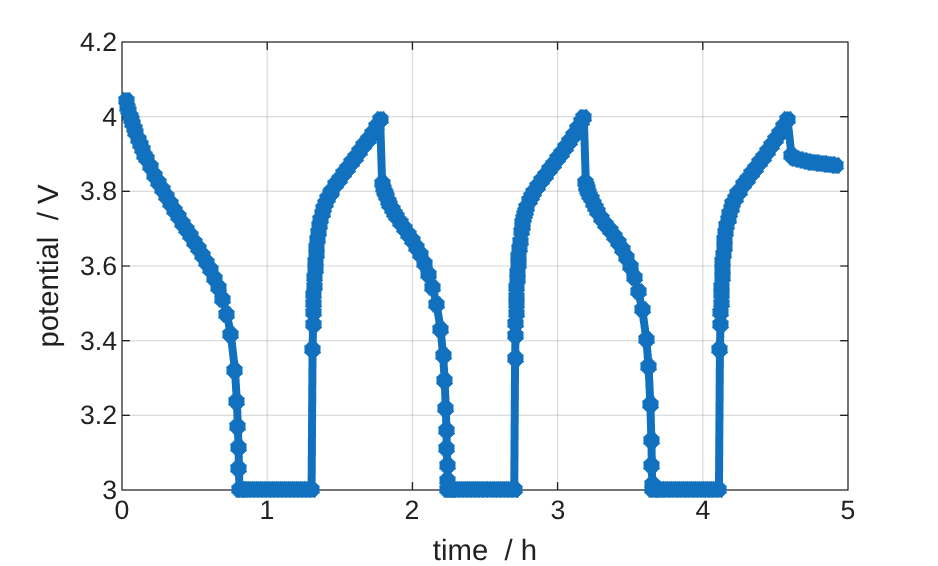

states = output.states;

E = cellfun(@(x) x.Control.E, states);
I = cellfun(@(x) x.Control.I, states);
time = cellfun(@(x) x.time, states);

figure
plot(time/hour, E, '*-', 'linewidth', 3);
grid on
xlabel 'time  / h';
ylabel 'potential  / V';

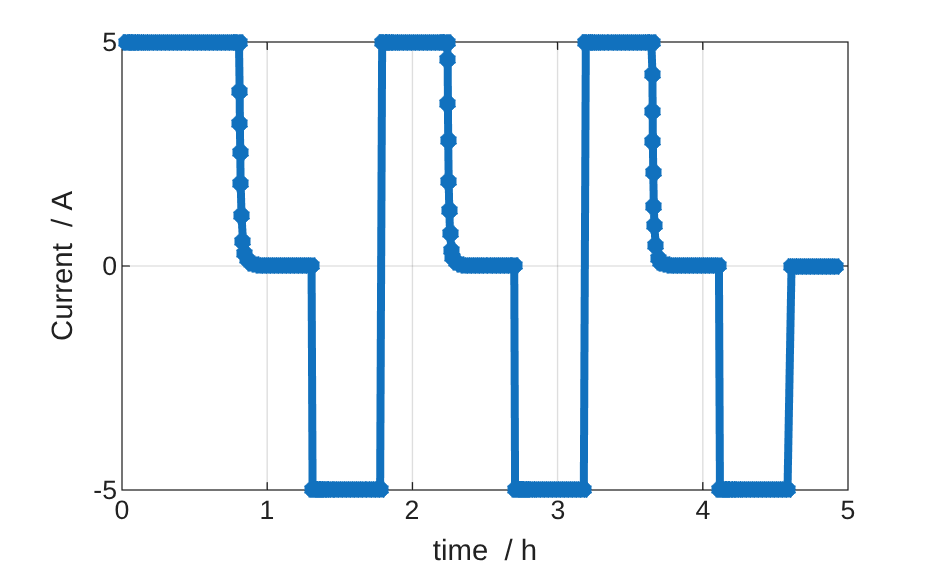


figure
plot(time/hour, I, '*-', 'linewidth', 3);
grid on
xlabel 'time  / h';
ylabel 'Current  / A';


%{
Copyright 2021-2026 SINTEF Industry, Sustainable Energy Technology
and SINTEF Digital, Mathematics & Cybernetics.

This file is part of The Battery Modeling Toolbox BattMo

BattMo is free software: you can redistribute it and/or modify
it under the terms of the GNU General Public License as published by
the Free Software Foundation, either version 3 of the License, or
(at your option) any later version.

BattMo is distributed in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
GNU General Public License for more details.

You should have received a copy of the GNU General Public License
along with BattMo.  If not, see <http://www.gnu.org/licenses/>.
%}